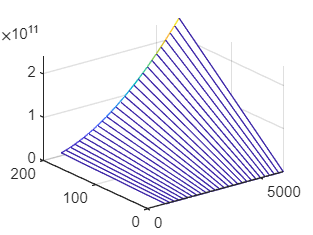

Drehzahl_max = 6000;    %Maximale Drehzahl [1/min]
Drehmoment_max = 200;   %Maximales Drehmoment [Nm]
Leistung_max = 120000;  %Maximale Leistung [W]
Drehzahl = [];
%Drehzahlvektor mit inkrement = 200 [1/min]
for i_Drehzahlband = 800:200:Drehzahl_max
    Drehzahl(:,end+1) = i_Drehzahlband;
end
%Willanslinie 
Drehmoment = [0 Drehmoment_max];
l_Drehzahl = length(Drehzahl);
Verbrauch = [];
for i_Verbrauch = 1:l_Drehzahl
b_abs = (1237000/200)*Drehmoment_max + ((Drehzahl(i_Verbrauch)*352.8)^1.8);
Verbrauch(1,i_Verbrauch) = 0;
Verbrauch(2,i_Verbrauch) = b_abs;
end
figure
mesh(Drehzahl, Drehmoment, Verbrauch)

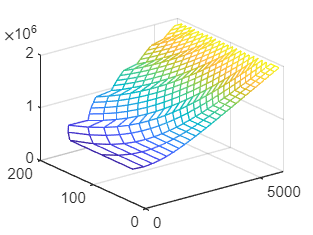

i_zaehler_row = 1;
i_zaehler_col = 1;
nmo_temp = [];
mmo_temp = [];
b_e_temp = [];
%Kurven gleicher Leistung
for i_leistung = 0:5:120   %Leistung P[kW] 20-120kW in 20er steps
   
    for i_leistung_drehzahl = 1:l_Drehzahl   %jede Drehzahlgerade 
        %Stützstellen Willanslinie
        nmo_stuetzstelle_0Nm = Verbrauch(1,i_leistung_drehzahl);
        nmo_stuetzstelle_200Nm = Verbrauch(2,i_leistung_drehzahl)/200;
        nmo_muschel = Drehzahl(i_leistung_drehzahl);
        %Gesuchtes Drehmoment
        m_muschel = (i_leistung*1000)/(nmo_muschel*(pi/30));
        %Geradengleichung aufstellen
        babs_muschel = nmo_stuetzstelle_0Nm + m_muschel * nmo_stuetzstelle_200Nm;        
            %liegt das gesuchte Moment in der range? wenn ja wird es in den
            %Vektor geschrieben
            if m_muschel <= Drehmoment_max    
               nmo_temp(i_zaehler_row, i_zaehler_col) = nmo_muschel;                    %aktuelle Drehzahl
               mmo_temp(i_zaehler_row, i_zaehler_col) = m_muschel;                      %aktuelles Moment
               b_e_temp(i_zaehler_row, i_zaehler_col) = babs_muschel/(i_leistung*1000); %Spezifischer Verbrauch
               i_zaehler_col = i_zaehler_col + 1;
            end       
    end
     i_zaehler_row = i_zaehler_row + 1;
     i_zaehler_col = 1;
end
nmo_temp(nmo_temp == 0) = nan;
mmo_temp(mmo_temp == 0) = nan;
b_e_temp(b_e_temp == 0) = nan;

mesh(nmo_temp,mmo_temp,b_e_temp)

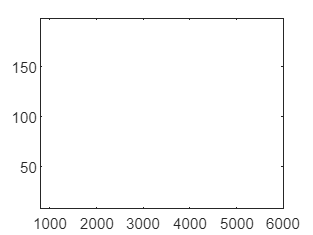


contour(nmo_temp, mmo_temp, b_e_temp, [196 198 200 202 204])